EN3551: DIGITAL SIGNAL PROCESSING

Assignment 2: Application of 2D-DCT for image compression

Index Number : 200377M

Tasks

- Download 3 images assigned to your index number. You have to select one more image of your choice, which is not in the provided set of images

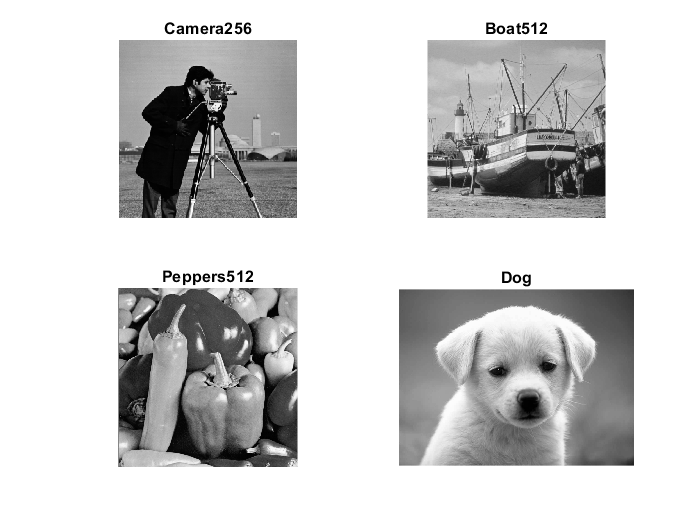

% Load the images
load('camera256.mat');  % Replace with your image file names
load('boat512.mat');
load('peppers512.mat');
image = imread("dog.jpg");
% Display the images
figure;
subplot(2, 2, 1);
imshow(camera256, []);
title('Camera256');

subplot(2, 2, 2);
imshow(boat512, []);
title('Boat512');

subplot(2, 2, 3);
imshow(peppers512, []);
title('Peppers512');

subplot(2, 2, 4);
imshow(image, []);
title('Dog');

- Compress each of these images by the DCT-based method described above with three quality levels. The quality levels are also assigned based on your index number

- Observe the results in terms of • percentage of zeros, • quality in terms of peak signal-to-noise ratio (see above), and • visual quality of the compressed images as related to the quality level.

When Quality Level = 60


Percentage of Zeros = 83.1192


Peak Signal-to-Noise Ratio = 32.5619


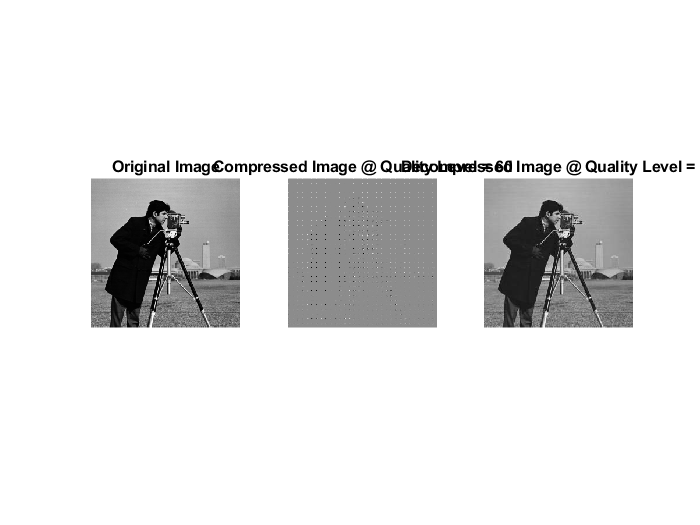

When Quality Level = 25


Percentage of Zeros = 90.6219


Peak Signal-to-Noise Ratio = 29.1581


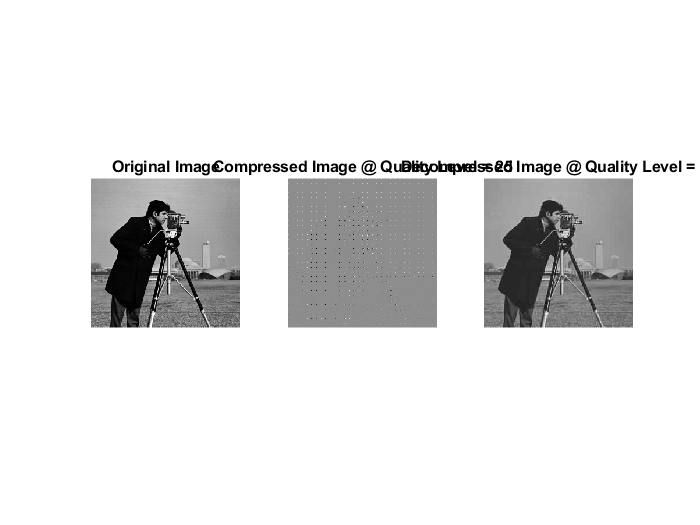

When Quality Level = 10


Percentage of Zeros = 95.0058


Peak Signal-to-Noise Ratio = 26.2428


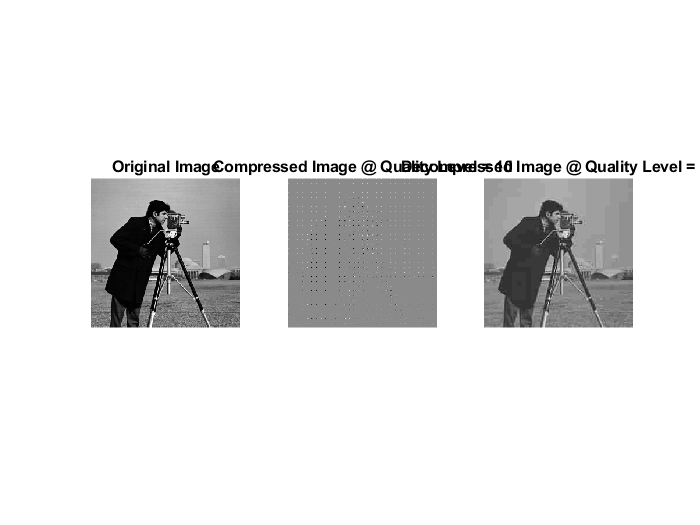



clc;
clear;
close all;

% Loading the required image
load("camera256.mat")
image = camera256;
% load("boat512.mat")
% image = boat512;
%load("peppers512.mat")
%image = peppers512;

[rows, cols, ~] = size(image);

% Determine the number of 8x8 blocks needed along each dimension
numBlocksRows = ceil(rows/8);
numBlocksCols = ceil(cols/8);

% Make a copy of the original image before doing operations using it
original_image = image;

% Divide the image into 8x8 blocks
image = mat2cell(image, 8 * ones(1, numBlocksRows), 8 * ones(1, numBlocksCols));

% Subtract 128 from every single element
image = cellfun(@(x) x - 128, image, 'UniformOutput', false);

% Apply DCT-2 to each block
image = cellfun(@dct2, image, 'UniformOutput', false);

% Setting the Quality Level
% qualitylevel = 60;
% qualitylevel = 25;
qualitylevel = 10;

% Define the quality levels for compression.
qualityLevels = [60, 25, 10];
numQualityLevels = length(qualityLevels);

% Loop through each quality level.
for level = 1:numQualityLevels
    % Calculate the quality factor for this level.
    qualitylevel = qualityLevels(level);
    % Defining Quantization Matrix
    quantizationMatrix = createJPEGQuantizationMatrix(qualitylevel);

    % Quantize each block
    quantizedmatrix = cellfun(@(x) quantizeDCTCoefficients(x,quantizationMatrix),image,'UniformOutput',false);

    % Combine quantizedmatrix into a single image
    quantizedmatrix = cell2mat(quantizedmatrix);
    quantizedmatrix_copy = quantizedmatrix;

    % Converting quantized matrix into a cell array
    quantizedmatrix = mat2cell(quantizedmatrix,8*ones(1,numBlocksRows),8*ones(1,numBlocksCols));

    % Encoding each block
    encodedmatrix = cellfun(@encodeDCTCoefficients,quantizedmatrix,'UniformOutput',false);

    % Pointwise multiplication of quantizationMatrix and quantizedmatrix
    dequantizedmatrix = cellfun(@(x) x.*quantizationMatrix,quantizedmatrix,'UniformOutput',false);

    % Apply inverse DCT-2 to each block
    level_offed_matrix = cellfun(@idct2,dequantizedmatrix,'UniformOutput',false);

    % Adding 128 to every single element
    decompressed_blocks = cellfun(@(x) x+128,level_offed_matrix,'UniformOutput',false);

    % Combine all blocks into a single image
    decompressed_image = cell2mat(decompressed_blocks);

    % Calculating Zero Percentage in the dequantizedmatrix
    dequantizedmatrix = cell2mat(dequantizedmatrix);
    zero_percentage = (nnz(dequantizedmatrix==0)/numel(dequantizedmatrix))*100;

    % Calculating the maximum light intensity of the original image using antilog of one side of the image
    max_intensity = 2^(log2(rows))-1;


    % Calculating Mean Squared Error by iteratively using mean() over the two axes of a squared error matrix
    % First, ensure that both original_image and decompressed_image have the same data type (e.g., double)
    original_image = double(original_image);
    decompressed_image = double(decompressed_image);

    % Now calculate the Mean Squared Error
    mean_squared_error = mean(mean((original_image - decompressed_image).^2));

    % Calculating Peak Signal-to-Noise Ratio
    peak_signal_to_noise_ratio = 10 * log10((max_intensity^2) / mean_squared_error);

    % Display the calculated performance metrics
    temp = "When Quality Level = " + num2str(qualitylevel);
    disp(temp);
    disp(" ");
    pm1 = "Percentage of Zeros = " + num2str(zero_percentage);
    disp(pm1);
    pm2 = "Peak Signal-to-Noise Ratio = " + num2str(peak_signal_to_noise_ratio);
    disp(pm2);

    % Displaying Images
    myfigure = figure();
    myfigure.WindowState = 'maximized';

    subplot(1, 3, 1);
    imshow(original_image, []);
    title('Original Image');

    subplot(1, 3, 2);
    imshow(cell2mat(quantizedmatrix), []);
    title_string = "Compressed Image @ Quality Level = " + num2str(qualitylevel);
    title(title_string);

    subplot(1, 3, 3);
    imshow(decompressed_image, []);
    title_string = "Decompressed Image @ Quality Level = " + num2str(qualitylevel);
    title(title_string);

    % Create a two-line title with a line break for the PSNR value.
    titleText = sprintf('Compressed, \nQuality Level = %d\nZeros: %.2f%%, \nPSNR: %.2f dB', qualitylevel, zero_percentage, peak_signal_to_noise_ratio);

end

function quantizationMatrix = createJPEGQuantizationMatrix(quality)
    % Define the standard JPEG quantization matrix for quality level 50
    standardQuantizationMatrix = [
        16, 11, 10, 16, 24, 40, 51, 61;
        12, 12, 14, 19, 26, 58, 60, 55;
        14, 13, 16, 24, 40, 57, 69, 56;
        14, 17, 22, 29, 51, 87, 80, 62;
        18, 22, 37, 56, 68, 109, 103, 77;
        24, 35, 55, 64, 81, 104, 113, 92;
        49, 64, 78, 87, 103, 121, 120, 101;
        72, 92, 95, 98, 112, 100, 103, 99
    ];
    
    % Quality should have values between 1 and 100
    if quality <= 0
        quality = 1;
    elseif quality > 100
        quality = 100;
    end
    
    % Adjust Quantization Matrix based on the desired quality level
    if quality < 50
        scaleFactor = 50 / quality;
    else
        scaleFactor = 2 - (quality / 50);
    end
    
    quantizationMatrix = round(standardQuantizationMatrix * scaleFactor);
    
    % Ensure that no values are less than 1
    quantizationMatrix(quantizationMatrix < 1) = 1;
end

% Define a function to quantize the matrix with quantizationMatrix
function quantizedmatrix = quantizeDCTCoefficients(matrix, quantizationMatrix)
    % Initialize the quantized matrix
    quantizedmatrix = round(matrix ./ quantizationMatrix);
end

% Define a function to encode [0,0] coefficient using differential PCM and encode AC coefficients with (run,level) pairs
function encodedmatrix = encodeDCTCoefficients(matrix)
    % Initialize the encoded matrix
    encodedmatrix = zeros(1, 64);
    
    % Encode the DC coefficient
    encodedmatrix(1) = matrix(1, 1);
    
    % Encode the AC coefficients
    index = 2;
    for i = 1:8
        for j = 1:8
            if i == 1 && j == 1
                continue;
            end
            if matrix(i, j) == 0
                index = index + 1;
            else
                encodedmatrix(index) = matrix(i, j);
                index = index + 1;
            end
        end
    end
end





